# Varying Parameters analysis

**Author(s): Vanja Vlasov, Systems Biochemistry Group, LCSB, University of Luxembourg.**

**Reviewer(s): Thomas Pfau, Systems Biology Group, LSRU, University of Luxembourg.**

**Ines Thiele, Systems Biochemistry Group, LCSB, University of Luxembourg**

In this tutorial, we show how computations are performed by varying one or two parameters over a fixed range of numerical values.

## EQUIPMENT SETUP

If necessary, initialise the cobra toolbox:

initCobraToolbox;



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

For solving linear programming problems in FBA analysis, certain solvers are required:

% solverOK = changeCobraSolver(solverName, solverType, printLevel, unchecked)

The present tutorial can run with [glpk package](https://opencobra.github.io/cobratoolbox/deprecated/docs/cobra/solvers/changeCobraSolver.html), which does not require additional installation and configuration. Although, for the analysis of large models is recommended to use the [GUROBI](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md) package.

Setup the appropriate solver for the machine you are using by removing the "%" (comment) sign for only the desired solver.

% changeCobraSolver('glpk','all');
% changeCobraSolver('tomlab_cplex','all');
% changeCobraASolver('ibm_cplex','all');
 changeCobraSolver ('gurobi', 'all');


 > Gurobi interface added to MATLAB path.
 > Solver for LPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MILPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for QPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MIQPproblems has been set to gurobi.
 > Solver gurobi not supported for problems of type NLP. Currently used: matlab 


## PROCEDURE

Before proceeding with the simulations, the path for the model needs to be set up:

% check if Recon3 exists:
% pathModel = '~/work/sbgCloud/data/models/unpublished/Recon3D_models/';
% filename = '2017_04_28_Recon3d.mat';
% load([pathModel, filename])
% model = modelRecon3model;
% clear modelRecon3model
% and if not
% select your own model, or use Recon2.0model instead filename='Recon3.0model';
global CBTDIR
load([CBTDIR filesep 'test' filesep 'models' filesep 'Recon2.0model.mat']);
model = Recon2model;
model.rxns = strrep(model.rxns, '(', '[');
model.rxns = strrep(model.rxns, ')', ']');
clear Recon2model

In this tutorial, the provided model is a generic model of the human cellular metabolism, Recon 3D$$^1$. Therefore, we assume, that the cellular objectives include energy production or optimisation of uptake rates and by-product secretion for various physiological functions of the human body.

The metabolites structures and reactions are from the Virtual Metabolic Human database (VMH, [http://vmh.life](http://vmh.life)).

## TROUBLESHOOTING

If there are multiple energy sources available in the model; Specifying more constraints is necessary. If we do not do that, we will have additional carbon and oxygen energy sources available in the cell and the maximal ATP production. 

To avoid this issue, all external carbon sources need to be closed.

%Closing the uptake of all energy and oxygen sources
idx=strmatch('Exchange/demand reaction',model.subSystems);
c=0;
for i=1:length(idx)
    if model.lb(idx(i))~=0
        c=c+1;
        uptakes{c}=model.rxns{idx(i)};
    end
end
% If you use Recon3.0 model, than:
% modelalter = model;
% modelalter = changeRxnBounds(modelalter, uptakes, 0, 'b');
% modelalter = changeRxnBounds(modelalter, 'EX_HC00250[e]', -1000, 'l');

% The alternative way to do that, in case you were using another large model, 
% that does not contain defined Subsystem is
% to find uptake exchange reactions with following codes:
% [selExc, selUpt] = findExcRxns(model);
% uptakes = model.rxns(selUpt);

% Selecting from the exchange uptake reactions those 
% which contain at least 1 carbon in the metabolites included in the reaction:
 subuptakeModel = extractSubNetwork(model, uptakes);
 hiCarbonRxns = findCarbonRxns(subuptakeModel,1);
% Closing the uptake of all the carbon sources
 modelalter = model;
 modelalter = changeRxnBounds(modelalter, hiCarbonRxns, 0, 'b');
% Closing other oxygen and energy sources
 exoxygen = {'EX_adp'
    'EX_amp[e]'
    'EX_atp[e]'
    'EX_co2[e]'
    'EX_coa[e]'
    'EX_fad[e]'
    'EX_fe2[e]'
    'EX_fe3[e]'
    'EX_gdp[e]'
    'EX_gmp[e]'
    'EX_gtp[e]'
    'EX_h[e]'
    'EX_h2o[e]'
    'EX_h2o2[e]'
    'EX_nad[e]'
    'EX_nadp[e]'
    'EX_no[e]'
    'EX_no2[e]'
    'EX_o2s[e]'};
modelalter = changeRxnBounds (modelalter, exoxygen, 0, 'l');

## Robustness analysis

Robustness analysis is applied to estimate and visualise how changes in the concentration of an environmental parameter (exchange rate) or internal reaction effect on the objective$$^2$. If we are interested in varying $$v_{j}$ between two values, i.e., $$v_{j,min}$ and $$v_{j,max}$, we can solve $$l$ optimisation problems:


$$\begin{array}{ll}
\max Z_{k}= c^{T}v \\
\text{s.t.} & k =1,...,l,\\
& Sv=0,\\
\text{fixing} & v_{j}=v_{j,min}+ \frac{(k-1)}{(l-1)}*(v_{j,max}-v_{j,min})\\
\text{constraints} & v_{i,min}\leq v_{i} \leq v_{i,max}, i=1,...,n,i \neq j
 \end{array}$$


The function `robustnessAnalysis()` is used for this analysis:

% [controlFlux, objFlux] = robustnessAnalysis(model, controlRxn, nPoints,...
%      plotResFlag, objRxn,objType)

where inputs are a COBRA model, a reaction that has been analysed and optional inputs:

% INPUTS
% model         COBRA model structure
% controlRxn    Reaction of interest whose value is to be controlled
%
% OPTIONAL INPUTS
% nPoints       Number of points to show on plot (Default = 20)
% plotResFlag   Plot results (Default true)
% objRxn        Objective reaction to be maximized
%               (Default = whatever is defined in model)
% objType       Maximize ('max') or minimize ('min') objective
%               (Default = 'max')
%
% OUTPUTS
% controlFlux   Flux values within the range of the maximum and minimum for
%               a reaction of interest
% objFlux       Optimal values of objective reaction at each control
%               reaction flux value

Here, we will investigate how robust the maximal ATP production of the network (i.e., the maximal flux through '[`DM_atp_c_`](http://vmh.life/#human/all/DM_atp_c_)`'`) is with respect to varying glucose uptake rates and fixed oxygen uptake. 

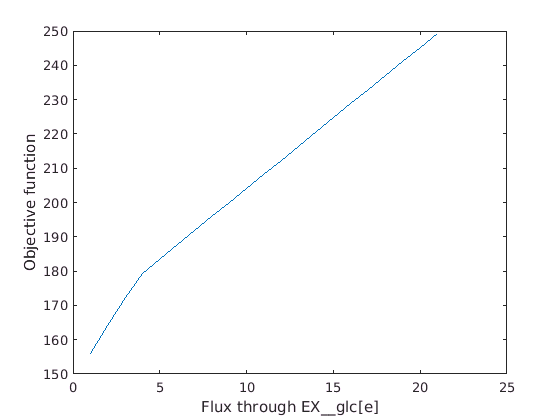

modelrobust = modelalter;
modelrobust = changeRxnBounds(modelrobust, 'EX_o2[e]', -17, 'b');
AtpRates = zeros(21, 1);
for i = 0:20
    modelrobust = changeRxnBounds(modelrobust, 'EX_glc[e]', -i, 'b');
    modelrobust = changeObjective(modelrobust, 'DM_atp_c_');
    FBArobust = optimizeCbModel(modelrobust, 'max');
    AtpRates(i+1) = FBArobust.f;
end
plot (1:21, AtpRates)
xlabel('Flux through EX__glc[e]')
ylabel('Objective function')

We can also investigate the robustness of the maximal ATP production when the available glucose amount is fixed, while different levels of oxygen are available.

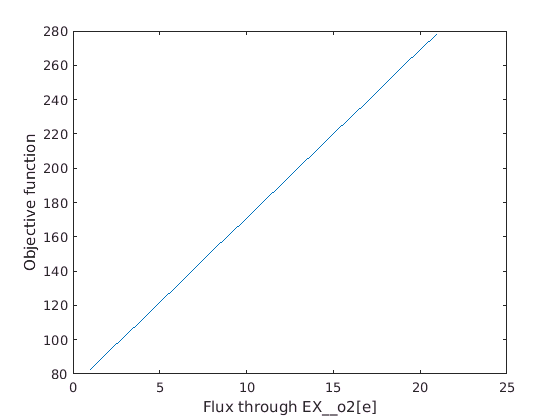

modelrobustoxy = modelalter;
modelrobustoxy = changeRxnBounds(modelrobustoxy, 'EX_glc[e]', -20, 'b');
AtpRatesoxy = zeros(21, 1);
for i = 0:20
    modelrobustoxy = changeRxnBounds(modelrobustoxy, 'EX_o2[e]', -i, 'b');
    modelrobustoxy = changeObjective(modelrobustoxy, 'DM_atp_c_');
    FBArobustoxy = optimizeCbModel(modelrobustoxy, 'max');
    AtpRatesoxy(i+1) = FBArobustoxy.f;
end
plot (1:21, AtpRatesoxy)
xlabel('Flux through EX__o2[e]')
ylabel('Objective function')

-        **Double robust analysis**

Performs robustness analysis for a pair of reactions of interest and an objective of interest. The double robust analysis is implemented with the function `doubleRobustnessAnalysis()`.

% [controlFlux1, controlFlux2, objFlux] = doubleRobustnessAnalysis(model,...
%  controlRxn1, controlRxn2, nPoints, plotResFlag, objRxn, objType)

The inputs are a COBRA model, two reactions for the analysis and optional inputs:

%INPUTS
% model         COBRA model to analyse,
% controlRxn1   The first reaction for the analysis,
% controlRxn2   The second reaction for the analysis;
%
%OPTIONAL INPUTS
% nPoints       The number of flux values per dimension (Default = 20)
% plotResFlag   Indicates whether the result should be plotted (Default = true)
% objRxn        is objective to be used in the analysis (Default = whatever
%               is defined in model)
% objType       Direction of the objective (min or max)
%               (Default = 'max')

Double robustness analysis in progress ...
1%      [                                        ]2%      [                                        ]3%      [.                                       ]4%      [.                                       ]5%      [..                                      ]6%      [..                                      ]7%      [..                                      ]8%      [...                                     ]9%      [...                                     ]10%     [....                                    ]11%     [....                                    ]12%     [....                                    ]13%     [.....                                   ]14%     [.....                                   ]15%     [......                                  ]16%     [......                                  ]17%     [......                                  ]18%     [.......                                 ]19%     [.......                                 ]20%    

controlFlux1 =   -20.0000
  -17.7778
  -15.5556
  -13.3333
  -11.1111
   -8.8889
   -6.6667
   -4.4444
   -2.2222
         0


controlFlux2 =   -17.0000
  -15.1111
  -13.2222
  -11.3333
   -9.4444
   -7.5556
   -5.6667
   -3.7778
   -1.8889
         0


objFlux =   249.3932  230.8625  212.3319  193.8013  175.2707  156.7401  138.2095  119.6789  101.1483   82.6176
  240.2428  221.7122  203.1816  184.6510  166.1204  147.5898  129.0592  110.5285   91.9979   73.4673
  231.0925  212.5619  194.0313  175.5007  156.9701  138.4394  119.9088  101.3782   82.8476   64.3170
  221.9422  203.4116  184.8810  166.3503  147.8197  129.2891  110.7585   92.2279   73.6973   55.1667
  212.7919  194.2612  175.7306  157.2000  138.6694  120.1388  101.6082   83.0776   64.5470   46.0163
  203.6415  185.1109  166.5803  148.0497  129.5191  110.9885   92.4578   73.9272   55.3966   36.8660
  194.4912  175.9606  157.4300  138.8994  120.3687  101.8381   83.3075   64.7769   46.2463   27.7157
  185.3409  166.8103  148.2796  129.7490  111.2184   92.6878   74.1572   55.6266   37.0960   18.5654
  174.2156  156.9640  139.1293  120.5987  102.0681   83.5375   65.0069   46.4763   27.9456    9.4150
  156.0371  138.7855  121.5339  104.2823   87.0306   69.7790   52.5274   35.2758 

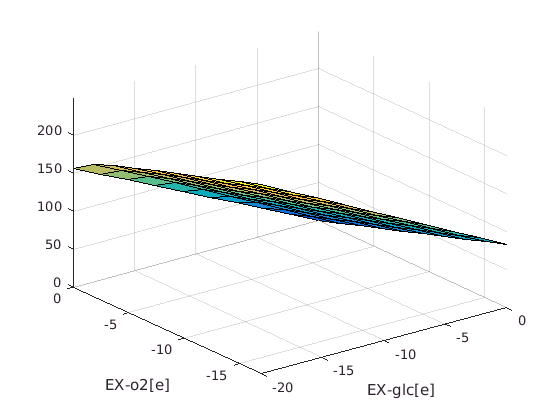

modeldrobustoxy = modelalter;
modeldrobustoxy = changeRxnBounds(modeldrobustoxy, 'EX_glc[e]', -20, 'l');
modeldrobustoxy = changeRxnBounds(modeldrobustoxy, 'EX_o2[e]', -17, 'l');
[controlFlux1, controlFlux2, objFlux] = doubleRobustnessAnalysis(modeldrobustoxy,...
    'EX_glc[e]', 'EX_o2[e]', 10, 1, 'DM_atp_c_', 'max')

## **Phenotypic phase plane analysis (PhPP)**

The PhPP is a method for describing in two or three dimensions, how the objective function would change if additional metabolites were given to the model$$^3$. 

Essentially PhPP performs a `doubleRobustnessAnalysis()`, with the difference that shadow prices are retained. The code is as follows-

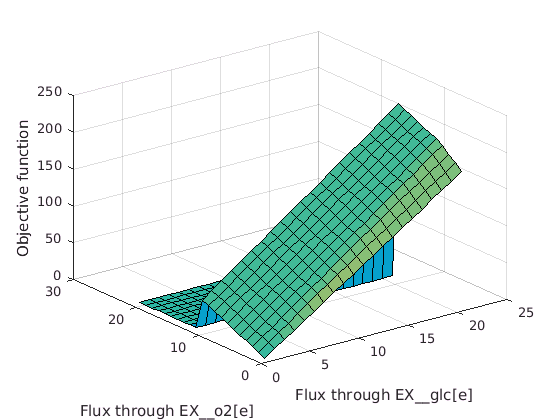

modelphpp = modelalter;
ATPphppRates = zeros(21);
for i = 0:10
    for j = 0:20
        modelphpp = changeRxnBounds(modelphpp, 'EX_glc[e]', -i, 'b');
        modelphpp = changeRxnBounds(modelphpp, 'EX_o2[e]', -j, 'b');
        modelphpp = changeObjective(modelphpp, 'DM_atp_c_');
        FBAphpp = optimizeCbModel(modelphpp, 'max');
        ATPphppRates(i+1,j+1) = FBAphpp.f;
    end
end

surfl(ATPphppRates) % 3d plot
xlabel('Flux through EX__glc[e]')
ylabel('Flux through EX__o2[e]')
zlabel('Objective function')

To generate a 2D plot: `pcolor(ATPphppRates)`

Alternatively, use the function `phenotypePhasePlane()`. This function also draws the line of optimality, as well as the shadow prices of the metabolites from the two control reactions. In this case, control reactions are `'`[`EX_glc[e]`](https://vmh.life/#reaction/EX_glc(e))`'` and '[`EX_o2[e]`](https://vmh.life/#reaction/EX_o2(e))'. The line of optimality signifies the state wherein, the objective function is optimal. In this case it is '[`DM_atp_c_`](http://vmh.life/#human/all/DM_atp_c_)'.

generating PhPP

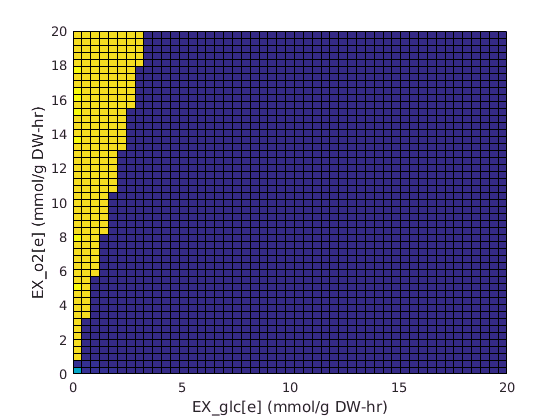

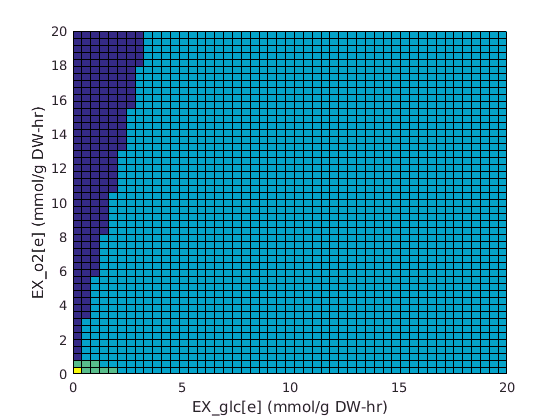

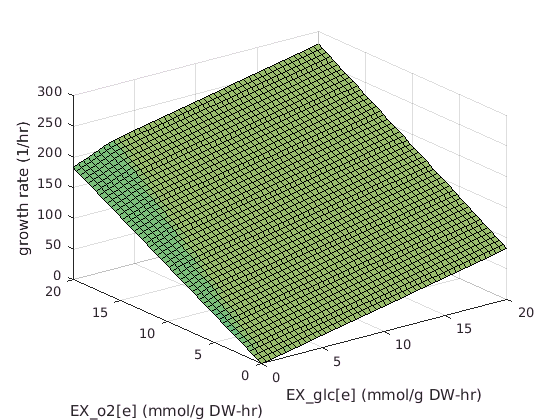

modelphpp = changeObjective (modelphpp, 'DM_atp_c_');
[growthRates, shadowPrices1, shadowPrices2] = phenotypePhasePlane(modelphpp,...
    'EX_glc[e]', 'EX_o2[e]');

## REFERENCES 

[1] Thiele, I., et al. A community-driven global reconstruction of human metabolism. *Nat. Biotechnol., *31(5), 419–425 (2013).

[2] Edwards, J.S., Palsson, B. Ø. Robustness analysis of the Escherichia coli metabolic network. *Biotechnology Progress, *16(6):927-939 (2000).

[3] Edwards, J.S., Ramakrishna, R., Palsson, B. Ø. Characterizing the metabolic phenotype: A phenotype phase plane analysis. *Biothechnology and Bioengineering*, 77:27-36 (2002).